# Reinforcement Learning

Reinforcement learning refers to machine learning protocols which create predicitve models through the testing in certain digitial enviornments, with certain outcomes being postiively weighted (or "rewarded") and others being negatviely weighted ("punished"). Reinfrocement learning can be a great way to model real life situations in which behaviro can be probablistiic. In the case of this module, the "Cart pole" situation is being modeled. A model is trying to have a moving cart is balance a pole. MATLAB has built in functions which can model this situation quite well. 

## **Creating an enviornment**

clear
%%%Code and tutorial from:
%%% https://www.mathworks.com/help/reinforcement-learning/ug/train-dqn-agent-to-balance-cart-pole-system.html

%%%Define a predefined enviornment for the model
env = rlPredefinedEnv('CartPole-Discrete')

env =   CartPoleDiscreteAction with properties:

                  Gravity: 9.8000
                 MassCart: 1
                 MassPole: 0.1000
                   Length: 0.5000
                 MaxForce: 10
                       Ts: 0.0200
    ThetaThresholdRadians: 0.2094
               XThreshold: 2.4000
      RewardForNotFalling: 1
        PenaltyForFalling: -5
                    State: [4×1 double]



%%%Get observation and action info from enviornment 
obsInfo = getObservationInfo(env)

obsInfo =   rlNumericSpec with properties:

     LowerLimit: -Inf
     UpperLimit: Inf
           Name: "CartPole States"
    Description: "x, dx, theta, dtheta"
      Dimension: [4 1]
       DataType: "double"


actInfo = getActionInfo(env)

actInfo =   rlFiniteSetSpec with properties:

       Elements: [-10 10]
           Name: "CartPole Action"
    Description: [0×0 string]
      Dimension: [1 1]
       DataType: "double"



%%%Random seed set 
rng(0)


%%% Neural net created and graphed 
net = [
    featureInputLayer(obsInfo.Dimension(1))
    fullyConnectedLayer(20)
    reluLayer
    fullyConnectedLayer(length(actInfo.Elements))
    ];

net = dlnetwork(net);
summary(net)

   Initialized: true

   Number of learnables: 142

   Inputs:
      1   'input'   4 features



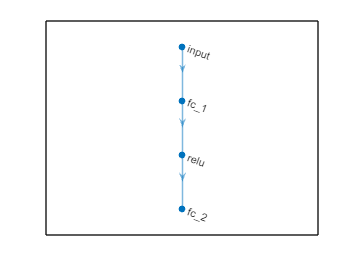


plot(net)

%%% Critic created 
critic = rlVectorQValueFunction(net,obsInfo,actInfo);
getValue(critic,{rand(obsInfo.Dimension)})

ans = 2×1 single column vector
   -0.2257
    0.4299


%%DQN Agent created with critic
agent = rlDQNAgent(critic);
getAction(agent,{rand(obsInfo.Dimension)})

ans = 1×1 cell array
    {[10]}



agent.AgentOptions.UseDoubleDQN = false;
agent.AgentOptions.TargetSmoothFactor = 1;
agent.AgentOptions.TargetUpdateFrequency = 4;
agent.AgentOptions.ExperienceBufferLength = 1e5;
agent.AgentOptions.MiniBatchSize = 256;
agent.AgentOptions.CriticOptimizerOptions.LearnRate = 1e-3;
agent.AgentOptions.CriticOptimizerOptions.GradientThreshold = 1;

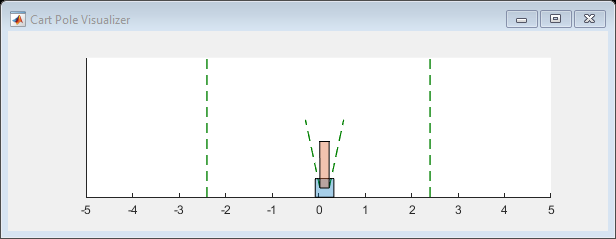

%%%Set train options before training
trainOpts = rlTrainingOptions(...
    MaxEpisodes=1000, ...
    MaxStepsPerEpisode=500, ...
    Verbose=false, ...
    Plots="training-progress",...
    StopTrainingCriteria="AverageReward",...
    StopTrainingValue=480); 
%%%Plot env in order to view model as it is being trained
plot(env)

%%% Train model
trainingStats = train(agent,env,trainOpts);